function P_loss = calcHybridACConductorLoss(conductorType, dimensions, freqE, B_r, B_theta_m, l,sigma, mu_c)
 

### Skin depth for frequency

$$\delta=1 / \sqrt{\pi \mu_c \sigma f}$$, $$$
\delta=\sqrt{\frac{2 \rho}{\omega \mu_0}}
$$$

where $\rho$ is the conductor resistivity, $\omega$ the angular frequency and $\mu_0$the permeability of free space.

$\sigma$ : Conductivity

elec.T0.resistivity = 1.724E-8;  % 주어진 저항값 (옴·미터)
elec.T0.Conductivity = 1 / elec.T0.resistivity;  % 전기전도도 (S/m)
sigma=elec.T0.Conductivity;                      % [S/m]
rho  = 1/sigma    ;  % resistivity (옴·미터)
mu0  = 4*pi*10^-7 ;      % [H/m] 
mu_c=mu0          ; %도체와 공기중 투자율이 같은것으로 가정
omegaE=freq2omega(freqE);
% freqE=mech2elec(freqE,4)
% SkinDepth_delta=sqrt((2*rho)./(omegaE.*mu0))  ;     % [m]
% SkinDepth_delta_inmm=m2mm(SkinDepth_delta)  ;       %[mm]
% 주어진 매개변수로부터 스킨 깊이 계산
    delta = 1 ./ sqrt(pi * mu_c * sigma .* freqE); %[m]
    % delta=SkinDepth_delta_inmm;   % in [mm]


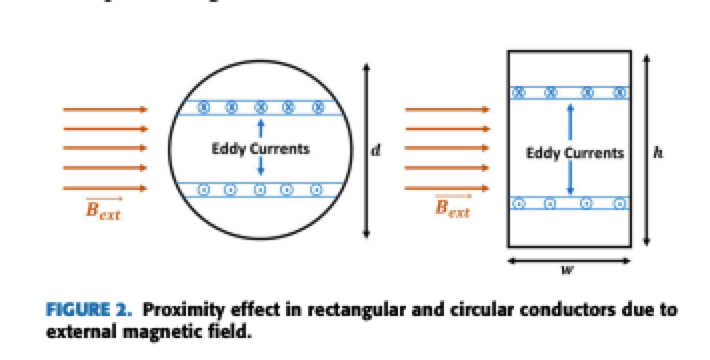

누설자속은 슬롯 옆에서 옴 

    % 도체의 형태에 따라 다른 계산 수행
    switch conductorType
        case 'rectangular'
            w = dimensions(1);   %[mm]
            w =mm2m(w)
            h = dimensions(2);   %[mm]
            h =mm2m(h)

#### *사각형 도체에 대한 수정된 스킨 깊이*


$$$\delta_w^{\prime}=\delta \cdot \sqrt{(w+h) /(2 h),} \quad \delta_h^{\prime}=\delta \cdot \sqrt{(w+h) /(2 w)}$$$


      % 사각형 도체에 대한 수정된 스킨 깊이
            delta_w_prime = delta.* sqrt((w + h) / (2 * h));
            delta_h_prime = delta.* sqrt((w + h) / (2 * w));

#### 무차원 형상파라미터


$$$\gamma, \gamma_w, \gamma_h, \gamma_w^{\prime}, \gamma_h^{\prime}$ Dimensionless parameters:
$$
\gamma=\frac{d}{\delta \cdot \sqrt{2}} \quad \gamma_w=\frac{w}{\delta} \quad \gamma_h=\frac{h}{\delta} \quad \gamma_w^{\prime}=\frac{w}{\delta_w^{\prime}} \quad \gamma_h^{\prime}=\frac{w}{\delta_h^{\prime}}
$$$$


            
            % 사각형 도체에 대한 무차원 매개변수
            gamma_w = w ./ delta;
            gamma_h = h ./ delta;
      
            gamma_w_prime = w ./ delta_w_prime;
            gamma_h_prime = h ./ delta_h_prime;
            % gamma_h_prime_w = w ./ delta_h_prime;

## 1D Method 

### Formular A


$$$g_2\left(\gamma_w, \gamma_h\right)=\left[\frac{\gamma_w}{\sigma \cdot \mu^2} \cdot \frac{\sinh \left(\gamma_h\right)-\sin \left(\gamma_h\right)}{\cosh \left(\gamma_h\right)+\cos \left(\gamma_h\right)}\right]$$$



$$$P_{\text {rect }}=\frac{\gamma_w\gamma_h^3}{6 \cdot \pi^2 \cdot \mu^2 \cdot \sigma} l B_m^2$$$


- MotorCAD 23.2.1 은 $$P_{\text {rect }}=\frac{\gamma_w\gamma_h^3}{12 \cdot \pi^2 \cdot \mu^2 \cdot \sigma} l B_m^2$$ 인거같은데?


$$$P_a=\frac{l_a w_c h_c^3 \sigma(\omega_e B)^2}{12}$$$


### Formular B(Improved One) $f_2$, $g_2$

P_rect = calcHybridStrandProx1D(gamma_w_prime(1), gamma_h_prime(1), mu0, sigma, lactive, Bm)  %[W]
% P_rectMCAD1D = calcHybridStrandProx1DMCAD(w, h, sigma, freqE,lactive/1000, Bm)



#### 2D Method

            % g2 함수 정의             % 손실 계산 함수
            g2_func = @(gamma_w, gamma_h) (gamma_w / (sigma * mu_c^2)) * ...
                (sinh(gamma_h) - sin(gamma_h)) / (cosh(gamma_h) + cos(gamma_h));
            


$$$P_{\text {rect }}=g_{1,2}\left(\gamma_w, \gamma_h\right) l B_r^2+g_{1,2}\left(\gamma_h, \gamma_w\right) l B_{\theta_m}^2$$$


           
            % 사각형 도체의 손실 계산
            P_loss = l * (g2_func(gamma_w_prime, gamma_h_prime) * B_r^2 + ...
                          g2_func(gamma_h_prime, gamma_w_prime) * B_theta_m^2);
            

[TB]

                     
        case 'circular'
            d = dimensions(1);

            % 원형 도체에 대한 무차원 매개변수
            gamma = d / (delta * sqrt(2));
            
            % 원형 도체의 손실 계산 (예시, 실제 계산식에 따라 수정 필요)
            P_loss = ...; % 원형 도체의 손실 계산식을 여기에 구현
            
        otherwise
            error('Unsupported conductor type. Choose either "rectangular" or "circular".');
    end
end
